# NEU 466M Final Project

Ellie Kim (rk27863)

#### b. Modeling I

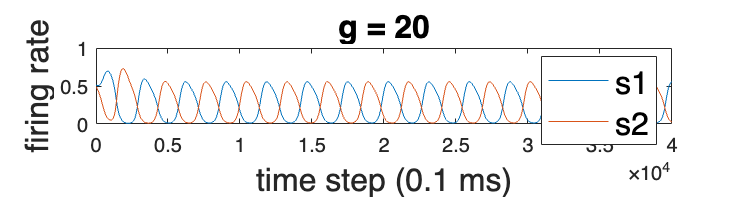

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 20; % adaptation effect
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt(s1(i), s2(i), a1(i), n1(i), g);
    s2(i + 1) = s2(i) + dt * ds_dt(s2(i), s1(i), a2(i), n2(i), g);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

figure
figWidth = 1500; % Width in pixels
figHeight = 400; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('g = 20', 'FontSize', 16)
legend('s1', 's2', 'FontSize', 16)
hold off

means = zeros(1, 50)

means =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


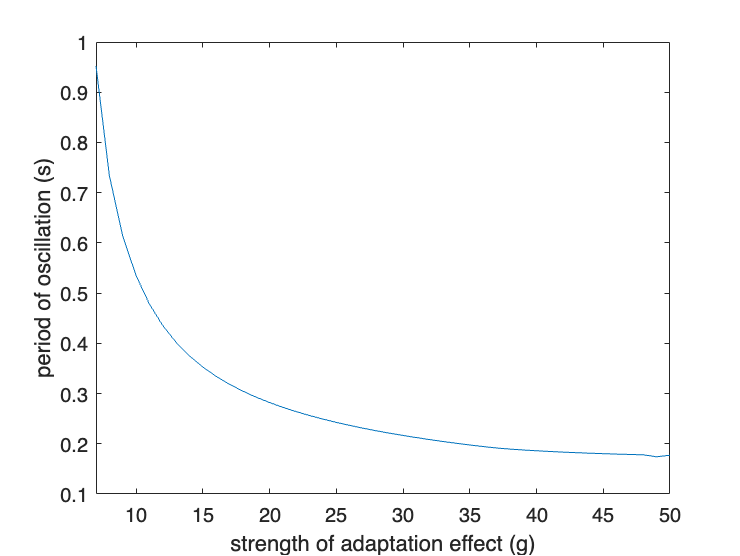

for g=1:50
    % initialize variables
    s1 = zeros(1, 40001);
    s2 = zeros(1, 40001);
    s1(1) = 0.51;
    s2(1) = 0.49;
    
    % initialize adaptation and noise
    a1 = zeros(1, 40001);
    a2 = zeros(1, 40001);
    n1 = zeros(1, 40001);
    n2 = zeros(1, 40001);
    
    % parameters
    dt = 0.1; % ms
    % g = 20; % adaptation effect
    sigma = 0; % zero noise
    i = 1; % index
    
    for t = 0:dt:4000
        % update synaptic action variables
        s1(i + 1) = s1(i) + dt * ds_dt(s1(i), s2(i), a1(i), n1(i), g);
        s2(i + 1) = s2(i) + dt * ds_dt(s2(i), s1(i), a2(i), n2(i), g);
    
        % update adaptation variables
        a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
        a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);
    
        % update noise terms
        n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
        n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);
    
        i = i + 1;
    end

    % isi distribution
    s_diff = s1 - s2;
    
    signs = sign(s_diff);
    diff_signs = diff(signs);
    switches = find(diff_signs);
    
    isi = diff(switches);

    means(g) = mean(isi) / 5000;
end

figure
plot(means)
xlim([7 50])
xlabel('strength of adaptation effect (g)')
ylabel('period of oscillation (s)')
hold off

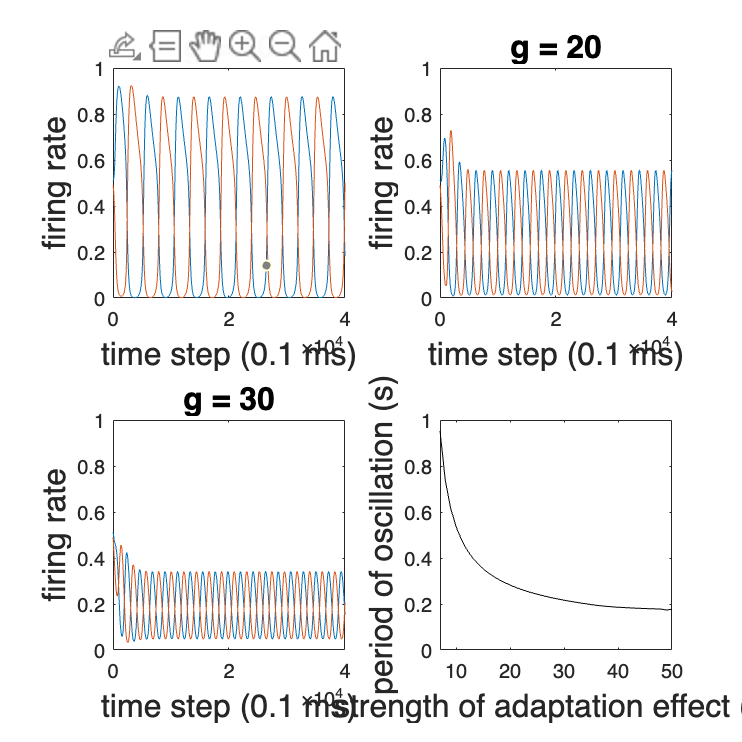

% varying g

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 10; % adaptation effect
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt(s1(i), s2(i), a1(i), n1(i), g);
    s2(i + 1) = s2(i) + dt * ds_dt(s2(i), s1(i), a2(i), n2(i), g);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

figure
figWidth = 1500; % Width in pixels
figHeight = 1500; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

% plot synaptic action variables
subplot(2, 2, 1)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('g = 10', 'FontSize', 16)
hold off

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 20; % adaptation effect
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt(s1(i), s2(i), a1(i), n1(i), g);
    s2(i + 1) = s2(i) + dt * ds_dt(s2(i), s1(i), a2(i), n2(i), g);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

subplot(2, 2, 2)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('g = 20', 'FontSize', 16)
hold off

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 30; % adaptation effect
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt(s1(i), s2(i), a1(i), n1(i), g);
    s2(i + 1) = s2(i) + dt * ds_dt(s2(i), s1(i), a2(i), n2(i), g);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

subplot(2, 2, 3)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('g = 30', 'FontSize', 16)
hold off

subplot(2, 2, 4)
plot(means, 'black')
xlim([7 50])
xlabel('strength of adaptation effect (g)', 'FontSize', 16)
ylabel('period of oscillation (s)', 'FontSize', 16)
hold off

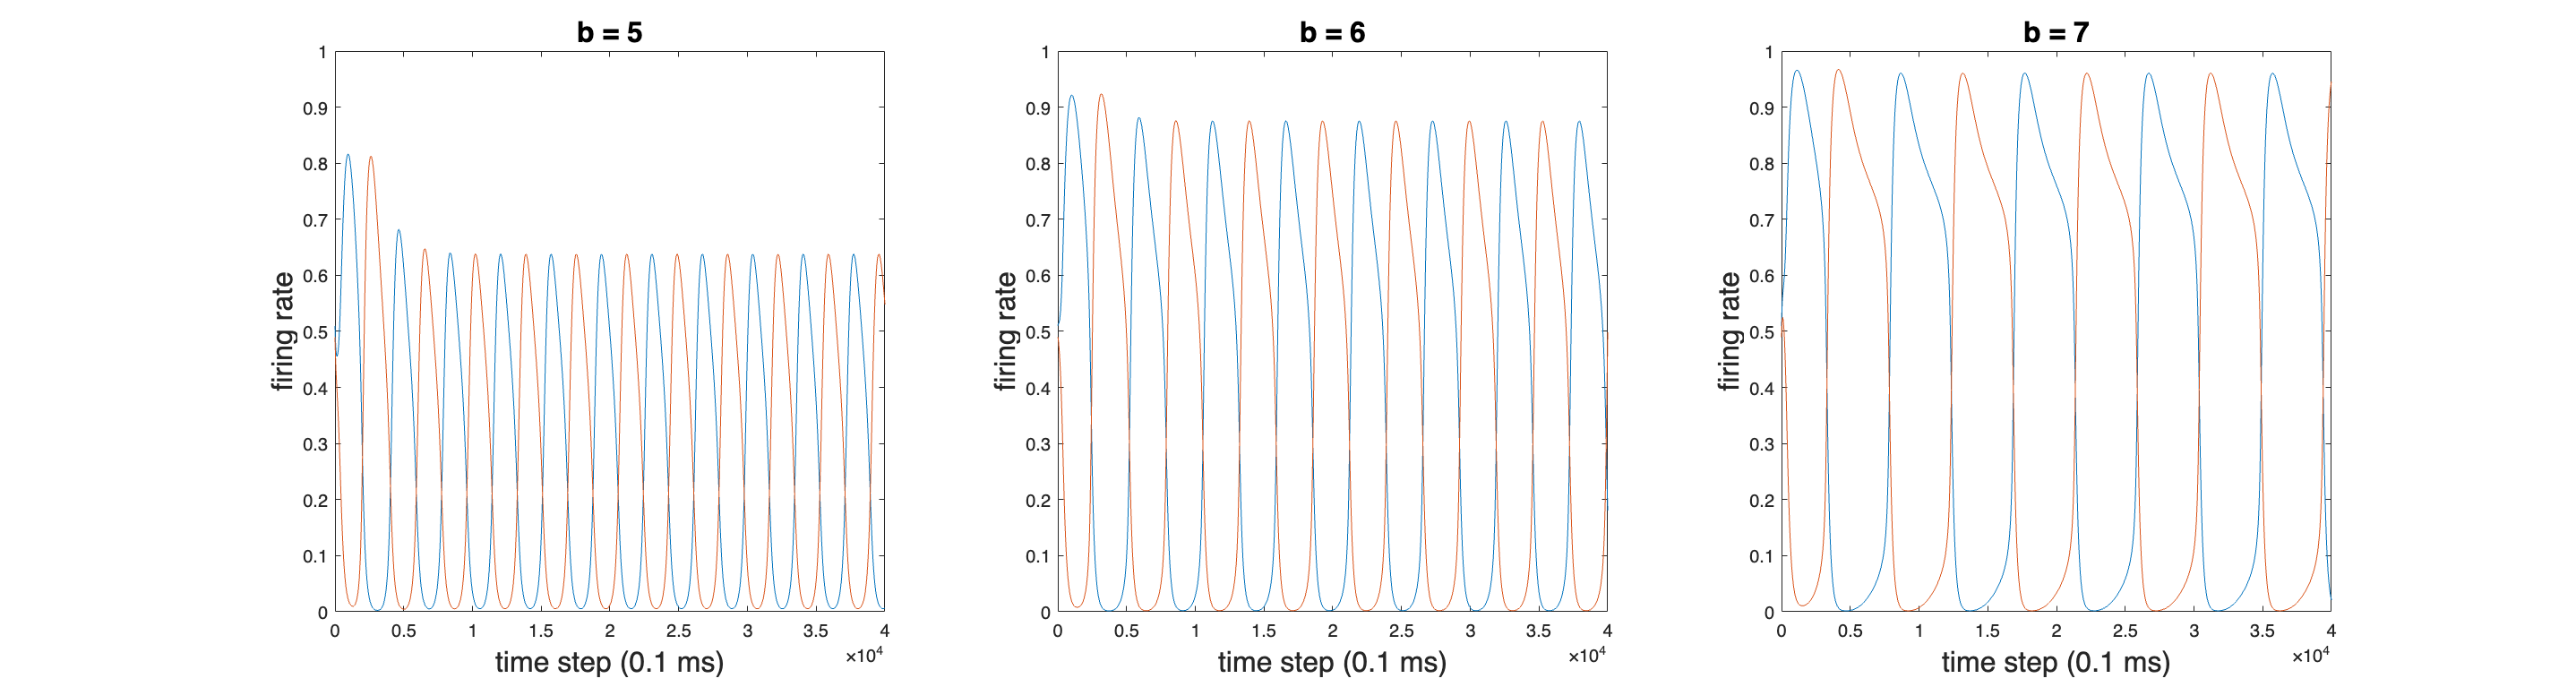

% fixed g, varying b

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% paraeanseters
dt = 0.1; % ms
g = 10; % adaptation effect
b = 5; % feedforward input
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

figure
figWidth = 1500; % Width in pixels
figHeight = 400; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

% plot synaptic action variables
subplot(1, 3, 1)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('b = 5', 'FontSize', 16)
hold off

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 10; % adaptation effect
b = 6; % feedforward input
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

subplot(1, 3, 2)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('b = 6', 'FontSize', 16)
hold off

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 10; % adaptation effect
b = 7; % feedforward input
sigma = 0; % zero noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

subplot(1, 3, 3)
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('b = 7', 'FontSize', 16)
hold off

#### c. Modeling II

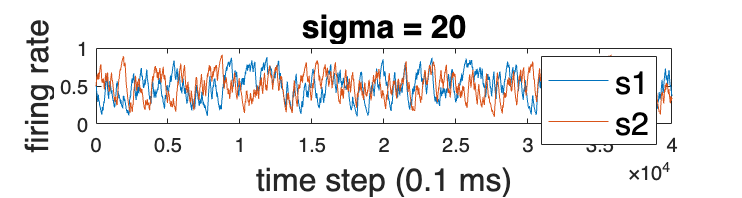

% no adaptation

% initialize variables
s1 = zeros(1, 40001);
s2 = zeros(1, 40001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 40001);
a2 = zeros(1, 40001);
n1 = zeros(1, 40001);
n2 = zeros(1, 40001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 7; % feedforward input
sigma = 20; % noise
i = 1; % index

for t = 0:dt:4000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

figure
figWidth = 1500; % Width in pixels
figHeight = 400; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])
plot(s1)
hold on
plot(s2)
xlim([0 40000])
ylim([0 1])
xlabel('time step (0.1 ms)', 'FontSize', 16)
ylabel('firing rate', 'FontSize', 16)
title('sigma = 20', 'FontSize', 16)
legend('s1', 's2', 'FontSize', 16)
hold off

mean_isis = zeros(1, 41);

j = 1;
for sigma = 0:0.5:20
    % initialize variables
    s1 = zeros(1, 60001);
    s2 = zeros(1, 60001);
    s1(1) = 0.51;
    s2(1) = 0.49;
    
    % initialize adaptation and noise
    a1 = zeros(1, 60001);
    a2 = zeros(1, 60001);
    n1 = zeros(1, 60001);
    n2 = zeros(1, 60001);
    
    % parameters
    dt = 0.1; % ms
    g = 20; % adaptation effect
    b = 7; % feedforward input
    i = 1; % index
    
    for t = 0:dt:6000
        % update synaptic action variables
        s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
        s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);
    
        % update adaptation variables
        a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
        a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);
    
        % update noise terms
        n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
        n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);
    
        i = i + 1;
    end
    
    % isi distribution
    s_diff = s1 - s2;
    
    signs = sign(s_diff);
    diff_signs = diff(signs);
    switches = find(diff_signs);
    
    isi = diff(switches);
    mean_isis(j) = mean(isi);
    j = j + 1;
end

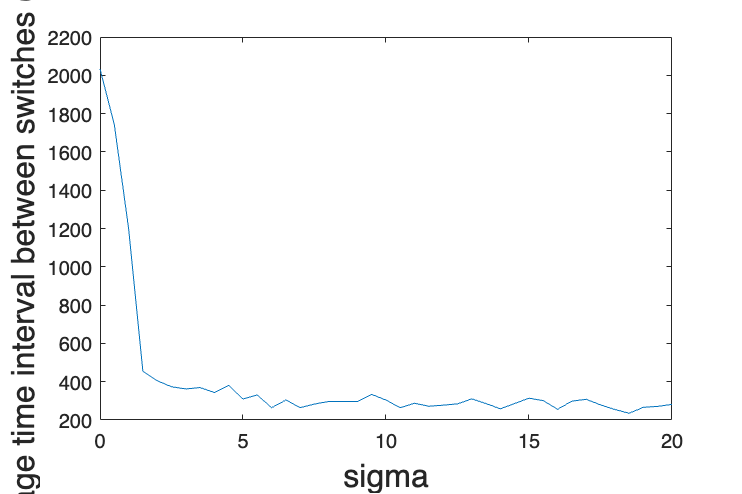

sigma = 0:0.5:20;

figure
figWidth = 900; % Width in pixels
figHeight = 600; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])
plot(sigma, mean_isis)
xlabel('sigma', 'FontSize', 16)
ylabel('average time interval between switches (0.1 ms)', 'FontSize', 16)
hold off

% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 7; % feedforward input
sigma = 2; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi2 = diff(switches);

% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 7; % feedforward input
sigma = 4; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi4 = diff(switches);

% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.51;
s2(1) = 0.49;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 7; % feedforward input
sigma = 6; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi6 = diff(switches);

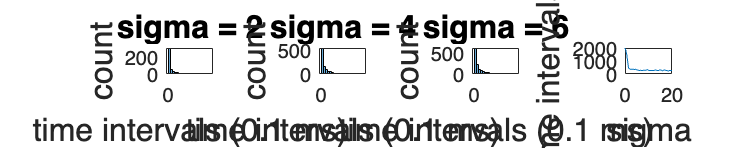

figure
figWidth = 1500; % Width in pixels
figHeight = 300; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

% plot isi distribution
subplot(1, 4, 1)
histogram(isi2, 20)
% ylim([0 56]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 2', 'FontSize', 16);

subplot(1, 4, 2)
histogram(isi4, 20)
% ylim([0 56]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 4', 'FontSize', 16);

subplot(1, 4, 3)
histogram(isi6, 20)
% ylim([0 56]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 6', 'FontSize', 16);
hold off

sigma = 0:0.5:20;
subplot(1, 4, 4)
plot(sigma, mean_isis)
xlabel('sigma', 'FontSize', 16)
ylabel('mean time intervals (0.1 ms)', 'FontSize', 16)
hold off

#### d. Analysis I

% compute STA
% no adaptation

% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 7; % feedforward input
sigma = 20; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);

positive_elements = diff_signs > 0;
negative_elements = diff_signs < 0;

s1_sup_dom = zeros(size(diff_signs));
s1_sup_dom(positive_elements) = 1;
s2_sup_dom = zeros(size(diff_signs));
s2_sup_dom(negative_elements) = 1;
s1_dom_sup = zeros(size(diff_signs));
s1_dom_sup(negative_elements) = 1;
s2_dom_sup = zeros(size(diff_signs));
s2_dom_sup(positive_elements) = 1;

% compute sta for s1
[c_s1, lag_s1] = xcorr(n1, s1_dom_sup);
% c_s1_f = fliplr(c_s1);
mid = floor(length(lag_s1)/2);
final_c_s1 = c_s1(mid - 12000: mid + 12000) / sum(s1_dom_sup)

final_c_s1 =    -0.0822   -0.1022   -0.1397   -0.1514   -0.1491   -0.1907   -0.1985   -0.2010   -0.1792   -0.2153   -0.2432   -0.2839   -0.3584   -0.3270   -0.2940   -0.3070   -0.2214   -0.1713   -0.1652   -0.1698   -0.1808   -0.1551   -0.2730   -0.2552   -0.3613   -0.4045   -0.3522   -0.2741   -0.2522   -0.2980   -0.2289   -0.2213   -0.2416   -0.2317   -0.2301   -0.2397   -0.2811   -0.3012   -0.2955   -0.3360   -0.3657   -0.3767   -0.3650   -0.3345   -0.3970   -0.3372   -0.3714   -0.4114   -0.3935   -0.3536


final_lag_s1 = lag_s1(mid - 12000: mid + 12000)

final_lag_s1 =       -12001      -12000      -11999      -11998      -11997      -11996      -11995      -11994      -11993      -11992      -11991      -11990      -11989      -11988      -11987      -11986      -11985      -11984      -11983      -11982      -11981      -11980      -11979      -11978      -11977      -11976      -11975      -11974      -11973      -11972      -11971      -11970      -11969      -11968      -11967      -11966      -11965      -11964      -11963      -11962      -11961      -11960      -11959      -11958      -11957      -11956      -11955      -11954      -11953      -11952



% compute sta for s2
[c_s2, lag_s2] = xcorr(n2, s2_sup_dom);
% c_s2_f = fliplr(c_s2);
mid = floor(length(lag_s2)/2);
final_c_s2 = c_s2(mid - 12000: mid + 12000) / sum(s2_sup_dom)

final_c_s2 =     0.1044    0.1581    0.1659    0.1647    0.1674    0.2240    0.2123    0.1904    0.1615    0.1520    0.0601    0.0576    0.0765    0.1014    0.0809    0.1464    0.1378    0.1186    0.1565    0.0614    0.0647    0.1758    0.2535    0.2677    0.2817    0.2880    0.3584    0.2562    0.2225    0.2218    0.2009    0.1542    0.1242    0.1552    0.0916    0.0651    0.0480    0.0186    0.0475    0.1062    0.0841    0.0806    0.0420    0.0880    0.0688    0.1414    0.0270   -0.0499   -0.0553   -0.0758


final_lag_s2 = lag_s2(mid - 12000: mid + 12000)

final_lag_s2 =       -12001      -12000      -11999      -11998      -11997      -11996      -11995      -11994      -11993      -11992      -11991      -11990      -11989      -11988      -11987      -11986      -11985      -11984      -11983      -11982      -11981      -11980      -11979      -11978      -11977      -11976      -11975      -11974      -11973      -11972      -11971      -11970      -11969      -11968      -11967      -11966      -11965      -11964      -11963      -11962      -11961      -11960      -11959      -11958      -11957      -11956      -11955      -11954      -11953      -11952



figure
figWidth = 1500; % Width in pixels
figHeight = 500; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

subplot(1, 2, 1)
plot(b * (1 + final_lag_s1), final_c_s1)
hold on
plot(b * (1 + final_lag_s2), final_c_s2)
xlim([-1000 1000])
xlabel('time to switch (0.1 ms)', 'FontSize', 16)
ylabel('stimulus', 'FontSize', 16)
legend('s1', 's2', 'FontSize', 16)
title('in-to-out direction', 'FontSize', 16)
hold off

% compute sta for s1
[c_s1, lag_s1] = xcorr(n1, s1_sup_dom);
% c_s1_f = fliplr(c_s1);
mid = floor(length(lag_s1)/2);
final_c_s1 = c_s1(mid - 12000: mid + 12000) / sum(s1_sup_dom)

final_c_s1 =    -0.3091   -0.2610   -0.2314   -0.3290   -0.3771   -0.3525   -0.2919   -0.2731   -0.2958   -0.3380   -0.2678   -0.1511   -0.1542   -0.1892   -0.1613   -0.1274   -0.1389   -0.1249   -0.1186   -0.1926   -0.1508   -0.1963   -0.1463   -0.1323   -0.0778   -0.1127   -0.1128   -0.0783   -0.1047   -0.1050   -0.1828   -0.2657   -0.2792   -0.3703   -0.3124   -0.3377   -0.2470   -0.2523   -0.2082   -0.2495   -0.2687   -0.3416   -0.3990   -0.4342   -0.3357   -0.3212   -0.3486   -0.2950   -0.2087   -0.1768


final_lag_s1 = lag_s1(mid - 12000: mid + 12000)

final_lag_s1 =       -12001      -12000      -11999      -11998      -11997      -11996      -11995      -11994      -11993      -11992      -11991      -11990      -11989      -11988      -11987      -11986      -11985      -11984      -11983      -11982      -11981      -11980      -11979      -11978      -11977      -11976      -11975      -11974      -11973      -11972      -11971      -11970      -11969      -11968      -11967      -11966      -11965      -11964      -11963      -11962      -11961      -11960      -11959      -11958      -11957      -11956      -11955      -11954      -11953      -11952



% compute sta for s2
[c_s2, lag_s2] = xcorr(n2, s2_dom_sup);
% c_s2_f = fliplr(c_s2);
mid = floor(length(lag_s2)/2);
final_c_s2 = c_s2(mid - 12000: mid + 12000) / sum(s2_dom_sup)

final_c_s2 =    -0.3302   -0.4506   -0.4154   -0.3670   -0.3392   -0.2968   -0.3116   -0.3921   -0.4171   -0.4844   -0.4193   -0.4043   -0.3015   -0.3157   -0.2582   -0.2931   -0.2376   -0.1898   -0.1363   -0.1471   -0.0961   -0.0326   -0.0194    0.0233    0.0730    0.1921    0.2237    0.2224    0.2120    0.2432    0.2951    0.2286    0.2414    0.2576    0.2995    0.2908    0.3778    0.3443    0.4484    0.4361    0.4049    0.3315    0.4091    0.3311    0.2892    0.3296    0.2538    0.2067    0.2655    0.3248


final_lag_s2 = lag_s2(mid - 12000: mid + 12000)

final_lag_s2 =       -12001      -12000      -11999      -11998      -11997      -11996      -11995      -11994      -11993      -11992      -11991      -11990      -11989      -11988      -11987      -11986      -11985      -11984      -11983      -11982      -11981      -11980      -11979      -11978      -11977      -11976      -11975      -11974      -11973      -11972      -11971      -11970      -11969      -11968      -11967      -11966      -11965      -11964      -11963      -11962      -11961      -11960      -11959      -11958      -11957      -11956      -11955      -11954      -11953      -11952


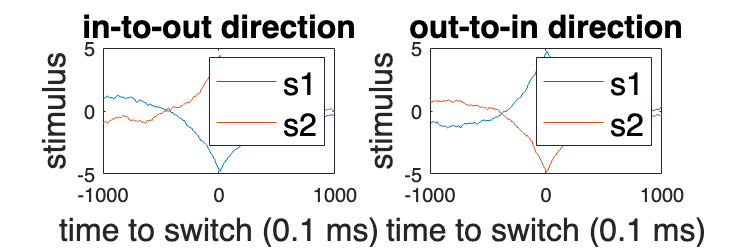


subplot(1, 2, 2)
plot(b * (1 + final_lag_s1), final_c_s1)
hold on
plot(b * (1 + final_lag_s2), final_c_s2)
xlim([-1000 1000])
xlabel('time to switch (0.1 ms)', 'FontSize', 16)
ylabel('stimulus', 'FontSize', 16)
legend('s1', 's2', 'FontSize', 16)
title('out-to-in direction', 'FontSize', 16)
hold off

#### e. Analysis II

% adaptation and noise
% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 10000; % adaptation effect
b = 6; % feedforward input
sigma = 1; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi1 = diff(switches);

% adaptation and noise
% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 10000; % adaptation effect
b = 6; % feedforward input
sigma = 5; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi5 = diff(switches);

% adaptation and noise
% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 10000; % adaptation effect
b = 6; % feedforward input
sigma = 10; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi10 = diff(switches);

% adaptation and noise
% initialize variables
s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 10000; % adaptation effect
b = 6; % feedforward input
sigma = 20; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi20 = diff(switches);

s1 = zeros(1, 400001);
s2 = zeros(1, 400001);
s1(1) = 0.5;
s2(1) = 0.5;

% initialize adaptation and noise
a1 = zeros(1, 400001);
a2 = zeros(1, 400001);
n1 = zeros(1, 400001);
n2 = zeros(1, 400001);

% parameters
dt = 0.1; % ms
g = 0; % adaptation effect
b = 6; % feedforward input
sigma = 20; % noise
i = 1; % index

for t = 0:dt:40000
    % update synaptic action variables
    s1(i + 1) = s1(i) + dt * ds_dt_b(s1(i), s2(i), a1(i), n1(i), g, b);
    s2(i + 1) = s2(i) + dt * ds_dt_b(s2(i), s1(i), a2(i), n2(i), g, b);

    % update adaptation variables
    a1(i + 1) = a1(i) + dt * da_dt(a1(i), s2(i), n1(i), g);
    a2(i + 1) = a2(i) + dt * da_dt(a2(i), s1(i), n2(i), g);

    % update noise terms
    n1(i + 1) = n1(i) + dt * dn_dt(n1(i), sigma);
    n2(i + 1) = n2(i) + dt * dn_dt(n2(i), sigma);

    i = i + 1;
end

% isi distribution
s_diff = s1 - s2;

signs = sign(s_diff);
diff_signs = diff(signs);
switches = find(diff_signs);

isi_noadapt = diff(switches);

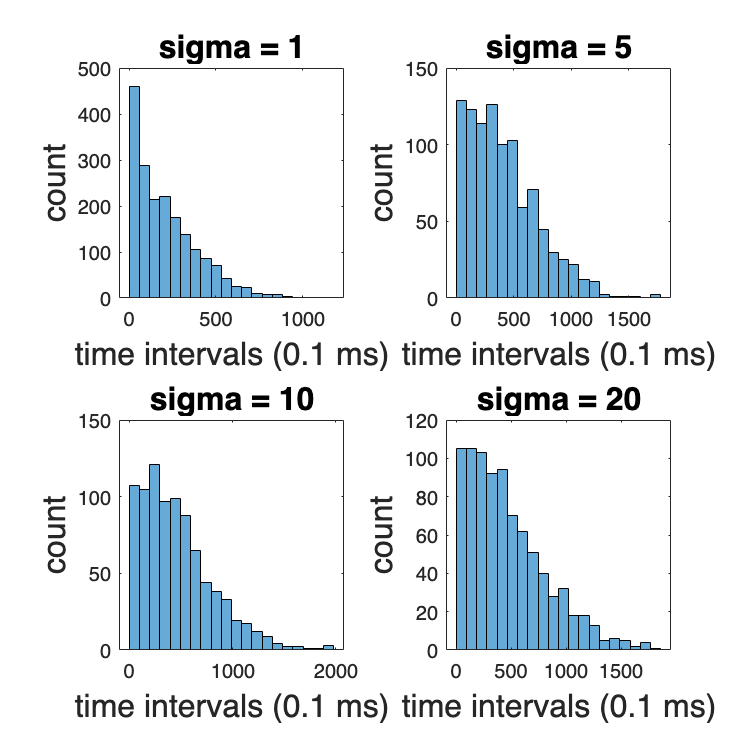

figure;
figWidth = 1500; % Width in pixels
figHeight = 1500; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

% edges = [0:100:2000];

% plot isi distribution
subplot(2, 2, 1)
histogram(isi1, 20)
% xlim([0 19000]);
% ylim([0 17]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 1', 'FontSize', 16);
hold off

subplot(2, 2, 2)
histogram(isi5, 20)
% xlim([0 19000]);
% ylim([0 16]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 5', 'FontSize', 16);

subplot(2, 2, 3)
histogram(isi10, 20)
% xlim([0 19000]);
% ylim([0 15]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 10', 'FontSize', 16);

subplot(2, 2, 4)
histogram(isi20, 20)
% xlim([0 19000]);
% ylim([0 15]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('count', 'FontSize', 16);
title('sigma = 20', 'FontSize', 16);
hold off

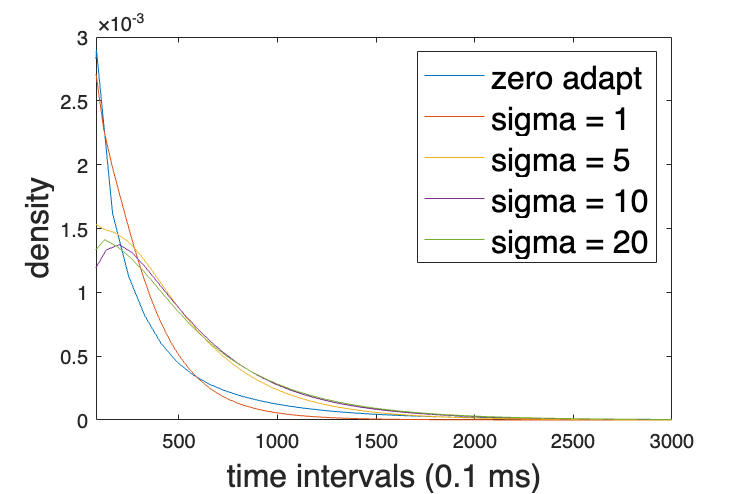

bw = 0.4;

figure
figWidth = 900; % Width in pixels
figHeight = 600; % Height in pixels
set(gcf, 'Position', [100, 100, figWidth, figHeight])

% Smooth and plot isi_noadapt
[f_noadapt, x_noadapt] = ksdensity(isi_noadapt, 'Support', 'positive', 'Bandwidth', bw);
plot(x_noadapt, f_noadapt, 'Color', '#0072BD');
hold on;

% Smooth and plot isi20
[f20, x20] = ksdensity(isi1, 'Support', 'positive', 'Bandwidth', bw);
plot(x20, f20, 'Color', '#D95319');

% Smooth and plot isi40
[f40, x40] = ksdensity(isi5, 'Support', 'positive', 'Bandwidth', bw);
plot(x40, f40, 'Color', '#EDB120');

% Smooth and plot isi60
[f60, x60] = ksdensity(isi10, 'Support', 'positive', 'Bandwidth', bw);
plot(x60, f60, 'Color', '#7E2F8E');

% Smooth and plot isi80
[f80, x80] = ksdensity(isi20, 'Support', 'positive', 'Bandwidth', bw);
plot(x80, f80, 'Color', '#77AC30');

xlim([80 3000]);
xlabel('time intervals (0.1 ms)', 'FontSize', 16);
ylabel('density', 'FontSize', 16);
% title('ISI Distributions');
legend({'zero adapt', 'sigma = 1', 'sigma = 5', 'sigma = 10', 'sigma = 20'}, 'FontSize', 16);
hold off;

function x = ds_dt (s, s_other, a, n, g)
    % parameters
    tau = 20; % ms
    w = 12;
    b = w / 2;

    x = - s + f(- w * s_other - g * a + b * (1 + n));
    x = x / tau;
end

% function to vary b
function x = ds_dt_b (s, s_other, a, n, g, b)
    % parameters
    tau = 20; % ms
    w = 12;

    x = - s + f(- w * s_other - g * a + b * (1 + n));
    x = x / tau;
end

% firing rate function
function y = f (x)
    y = exp(x) / (1 + exp(x));
end

% adaptation variables
function x = da_dt (a, s_other, n, g)
    % parameters
    tau_a = 200; % ms
    w = 12;
    b = w / 2;

    x = - a + f(- w * s_other - g * a + b * (1 + n));
    x = x / tau_a;
end

% noise terms
function x = dn_dt (n, sigma)
    tau_n = 4; % ms

    x = - n + sigma * sqrt(2 * tau_n) * randn;
    x = x / tau_n;
end